clear;clc;
white = double(imread('white.jpg'))/256;
black =  double(imread('black.jpg'))/256;

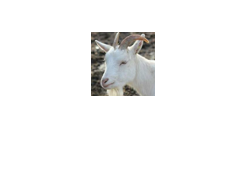

white = white(80:(80+170),150:(150+170),:);

white =imresize(white,[32 32]);
imshow(white);
white(white<0)=0;white(white>1)=1;


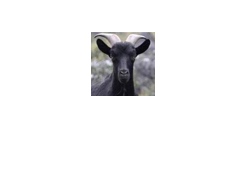

black = black(10:(10+140),339:(339+140),:);
black =imresize(black,[32 32]);
black(black<0)=0;black(black>1)=1;


%[640 480] /32 * 64
v=VideoReader("badapple.avi");
vv=VideoWriter('badappleBaa');
vv.FrameRate = v.FrameRate;
vv.open();
h=waitbar(0);
try
for i=1:round(v.Duration*v.FrameRate)
    waitbar(i/(v.Duration*v.FrameRate),h,sprintf("%d/%d",i,round(v.Duration*v.FrameRate)))
    frame = readFrame(v);
    frame=rgb2gray(frame);
    frame = imresize(frame,[480 640]/16) > 128;
    newframe = zeros([[480 640]/16*32 3]);
    for j=1:3
        newframe(:,:,j) = kron(frame,white(:,:,j));
        newframe(:,:,j) = newframe(:,:,j) + kron(~frame,black(:,:,j));
    end
    %imshow(newframe);
    vv.writeVideo(im2frame(newframe));
end

    close(h)
    vv.close();
catch ME
    close(h)
    vv.close();
end